# Bank Marketing, preparacion del dato paso a paso

T0 crudo, T1 arreglo de columnas y filas, T2 codificacion y escalado, T3 balanceo

clear; close all; clc

## T0: dato crudo

T0 = readtable('data/bank-full.csv', 'Delimiter', ';', 'TextType', 'string');
T0.y = categorical(T0.y);
size(T0)

ans =        45211          17


summary(T0)


T0: 45211×17 table

Variables:

    age: double
    job: string
    marital: string
    education: string
    default: string
    balance: double
    housing: string
    loan: string
    contact: string
    day: double
    month: string
    duration: double
    campaign: double
    pdays: double
    previous: double
    poutcome: string
    y: categorical (2 categories)

Statistics for applicable variables:

                 NumMissing       Min       Median        Max             Mean              Std      

    age              0              18         39            95           40.9362           10.6188  
    job              0                                                                               
    marital          0                                                                               
    education        0                                                                               
    default          0                                                      

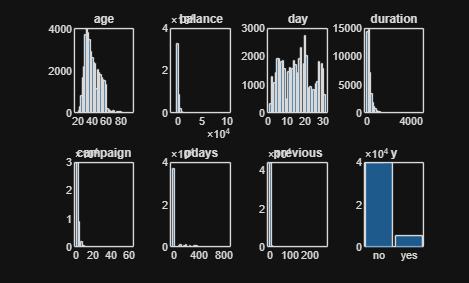

num = {'age','balance','day','duration','campaign','pdays','previous'};
cat = {'job','marital','education','default','housing','loan','contact','month','poutcome'};

figure
for k = 1:7
    subplot(2,4,k); histogram(T0.(num{k}), 40); title(num{k})
end
subplot(2,4,8); histogram(T0.y); title('y')

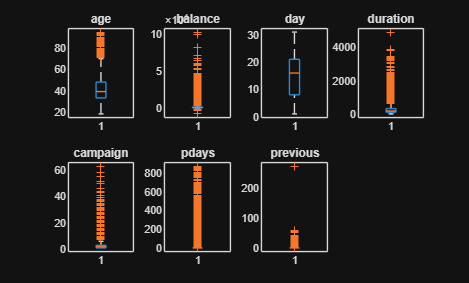


figure
for k = 1:7
    subplot(2,4,k); boxplot(T0.(num{k})); title(num{k})
end

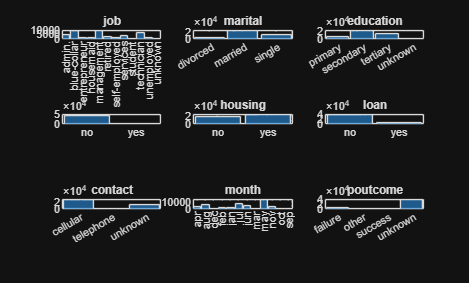


figure
for k = 1:9
    subplot(3,3,k); histogram(categorical(T0.(cat{k}))); title(cat{k})
end


countcats(T0.y)'

ans =        39922        5289


array2table(sum(T0{:,cat} == "unknown"), 'VariableNames', cat)

ans = 1×9 table
    job    marital    education    default    housing    loan    contact    month    poutcome
    ___    _______    _________    _______    _______    ____    _______    _____    ________

    288       0         1857          0          0        0       13020       0       36959  


## T1: columnas, filas, valores faltantes y atipicos

T1 = T0;
T1.duration = [];
T1 = T1(T1.job ~= "unknown", :);

meses = ["jan","feb","mar","apr","may","jun","jul","aug","sep","oct","nov","dec"];
[~, mes] = ismember(T1.month, meses);
T1.dia_anio = day(datetime(2009, mes, T1.day), 'dayofyear');
T1.day = [];  T1.month = [];

[~, T1.education] = ismember(T1.education, ["primary","secondary","tertiary"]);
for j = unique(T1.job)'
    m = T1.job == j;
    T1.education(m & T1.education == 0) = mode(T1.education(m & T1.education > 0));
end

tasa_base = mean(T1.y(T1.pdays < 0) == "yes")

tasa_base = 0.0917

bordes = [0 60 120 180 240 300 365 1000];
grupo = discretize(T1.pdays, bordes);
tasa = splitapply(@(y) mean(y == "yes"), T1.y, grupo);
table(bordes(1:end-1)', bordes(2:end)'-1, groupcounts(grupo(grupo > 0)), tasa, 'VariableNames', {'desde','hasta','n','tasa_si'})

ans = 7×4 table
    desde    hasta     n      tasa_si 
    _____    _____    ____    ________

       0       59      287     0.22997
      60      119     1577     0.40457
     120      179     1271     0.15657
     180      239     1483      0.3412
     240      299     1115     0.12287
     300      364     1800    0.085556
     365      999      691     0.27352


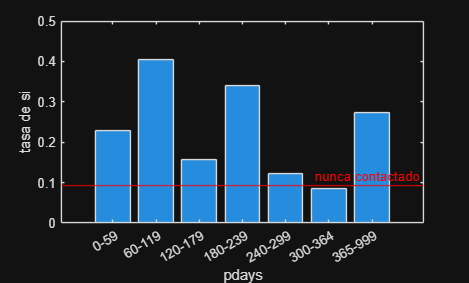

figure
bar(tasa); yline(tasa_base, 'r', 'nunca contactado')
xticklabels(bordes(1:end-1) + "-" + (bordes(2:end)-1)); ylabel('tasa de si'); xlabel('pdays')


umbral = 240;
T1.contactado_antes = double(T1.pdays >= 0 & T1.pdays <= umbral);
T1.pdays(T1.contactado_antes == 0) = umbral;

num1 = {'age','balance','campaign'};
for k = 1:3
    x = T1.(num1{k});
    q = quantile(x, [0.25 0.75]);
    li = q(1) - 1.5*(q(2)-q(1));  ls = q(2) + 1.5*(q(2)-q(1));
    fuera(k) = sum(x < li | x > ls);
    x(x < li) = li;  x(x > ls) = ls;
    T1.(num1{k}) = x;
end
array2table(fuera, 'VariableNames', num1)

ans = 1×3 table
    age    balance    campaign
    ___    _______    ________

    480     4712        3031  


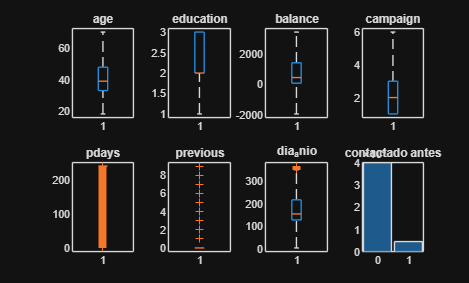

T1.previous = min(T1.previous, quantile(T1.previous, 0.99));

num1 = {'age','education','balance','campaign','pdays','previous','dia_anio'};
figure
for k = 1:7
    subplot(2,4,k); boxplot(T1.(num1{k})); title(num1{k})
end
subplot(2,4,8); histogram(categorical(T1.contactado_antes)); title('contactado antes')

size(T1)

ans =        44923          16


## T2: codificacion, estandarizacion y normalizacion

T2 = T1;
for v = {'default','housing','loan'}
    T2.(v{1}) = double(T1.(v{1}) == "yes");
end
for v = {'job','marital','contact','poutcome'}
    c = categorical(T2.(v{1}));
    D = array2table(dummyvar(c), 'VariableNames', matlab.lang.makeValidName(v{1} + "_" + string(categories(c))'));
    T2 = [T2 D];  T2.(v{1}) = [];
end
T2.poutcome_unknown = [];
T2 = movevars(T2, 'y', 'After', width(T2));
T2.Properties.VariableNames'

ans = 32×1 cell array
    {'age'              }
    {'education'        }
    {'default'          }
    {'balance'          }
    {'housing'          }
    {'loan'             }
    {'campaign'         }
    {'pdays'            }
    {'previous'         }
    {'dia_anio'         }
    {'contactado_antes' }
    {'job_admin_'       }
    {'job_blue_collar'  }
    {'job_entrepreneur' }
    {'job_housemaid'    }
    {'job_management'   }
    {'job_retired'      }
    {'job_self_employed'}
    {'job_services'     }
    {'job_student'      }
    {'job_technician'   }
    {'job_unemployed'   }
    {'marital_divorced' }
    {'marital_married'  }
    {'marital_single'   }
    {'contact_cellular' }
    {'contact_telephone'}
    {'contact_unknown'  }
    {'poutcome_failure' }
    {'poutcome_other'   }


size(T2)

ans =        44923          32


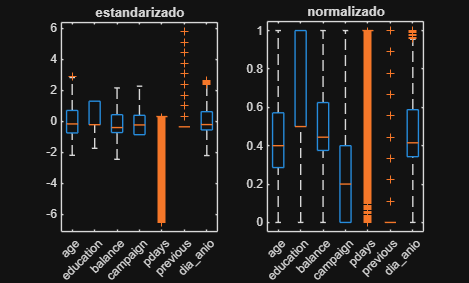


T2z = T2;  T2z{:,num1} = zscore(T2{:,num1});
T2n = T2;  T2n{:,num1} = normalize(T2{:,num1}, 'range');
figure
subplot(1,2,1); boxplot(T2z{:,num1}, 'Labels', num1); title('estandarizado')
subplot(1,2,2); boxplot(T2n{:,num1}, 'Labels', num1); title('normalizado')

## T3: balanceo por submuestreo de la clase no

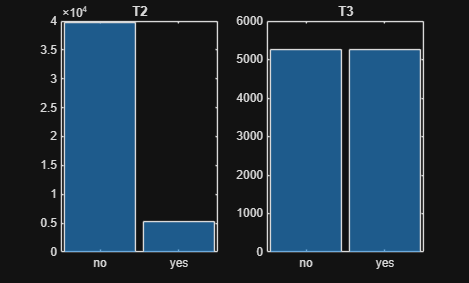

rng(1)
no = find(T2.y == "no");  si = find(T2.y == "yes");
sel = [no(randperm(numel(no), numel(si))); si];
T3z = T2z(sel, :);  T3n = T2n(sel, :);
figure
subplot(1,2,1); histogram(T2z.y); title('T2')
subplot(1,2,2); histogram(T3z.y); title('T3')

## Resumen y guardado

pasos = {'T0','T1','T2z','T3z'};
resumen = table();
for k = 1:4
    T = eval(pasos{k});
    resumen = [resumen; table(pasos(k), height(T), width(T)-1, sum(T.y == "no"), sum(T.y == "yes"), ...
               'VariableNames', {'Paso','Filas','Columnas','No','Si'})];
end
resumen

resumen = 4×5 table
     Paso      Filas    Columnas     No       Si 
    _______    _____    ________    _____    ____

    {'T0' }    45211       16       39922    5289
    {'T1' }    44923       15       39668    5255
    {'T2z'}    44923       31       39668    5255
    {'T3z'}    10510       31        5255    5255


save('bank_pasos.mat', 'T0', 'T1', 'T2', 'T2z', 'T2n', 'T3z', 'T3n')